## **Question 1**

**(1.1) *****Give a Nonlinear Programming (NLP) formulation for the profit maximization problem.*** 


$$\max \;z=\left(100-4q\right)q-4q-50$$


(1.2)  *Graphically and analitically identify the q value which maximizes the profit.*

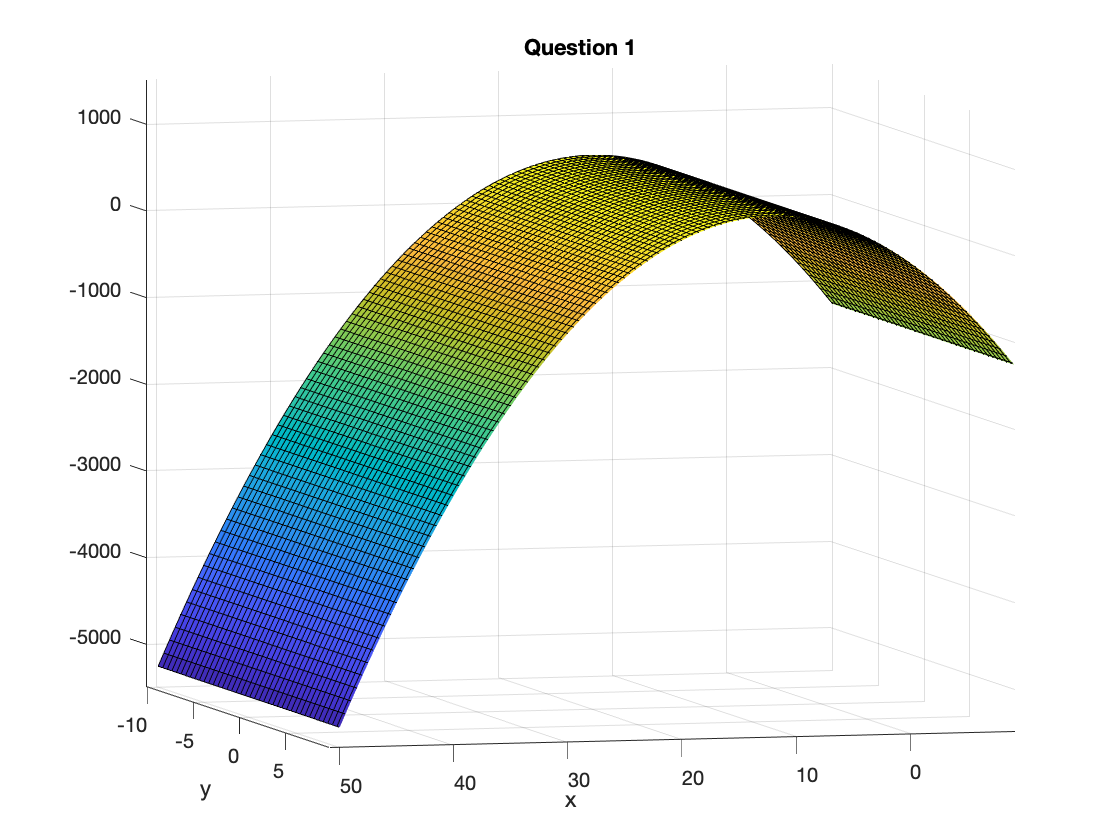

[x,y] = meshgrid(-10:0.5:50,-10:0.5:10);

myFunc = 100*x - 4*(x.^2) - 4*x - 50;

surf(x,y,myFunc)

title('Question 1')
xlabel('x')
ylabel('y')

xlim([-9.1 50.9])
ylim([-10.2 9.8])
zlim([-5486 1514])
view([165 6])

**(1.2) G*****raphically and analitically identify the q value which maximizes the profit.***

- datatip(chart,11.5,6,525,'Location','northeast');

- max Z = 526 and X = 11.5 - 12 (point defined as q in our equation)

**(1.3)***** What is the profitable range of production?***

- profitable interval for x is around [23,0.5]

## Question 2


$$\textrm{Consider}\textrm{the}\textrm{function}\;f\left(x\right)=x3+x2-2x+1$$
 

***(2.1) Find the stationary points of f and classify them as local min or local max.*** 		

- stationary point = means that function stops chaning and the f(x)' should be equal to zero.

- thus we'll first take first derivative of f(x),

           
$${f\left(x\right)}^{\prime } =3x^{2\;\;} +2x-2\;\;\;\;\;\;\;\textrm{indicates}\;\textrm{that}\;\textrm{x1},\textrm{x2}\in R\;\textrm{and}\;\Delta \;>0$$
 	


$$\begin{array}{l}
\Delta =b^2 -4\textrm{ac}\;\;\textrm{and}\;\Delta =24\;\textrm{satisfies}\;\Delta >0\;\textrm{and}\;\textrm{means}\;\textrm{that}\;\textrm{there}\;\textrm{should}\;\textrm{be}\;\textrm{at}\;\textrm{least}\;\textrm{two}\;\textrm{real}\;\textrm{roots}\;\textrm{of}\;\textrm{this}\\
\textrm{equation}\ldotp \textrm{More}\;\textrm{over}\;\;\textrm{x1}=\frac{-b+\sqrt{\Delta }}{2a}\;\textrm{and}\;\;\textrm{x2}=\;\frac{-b-\sqrt{\Delta }}{2a}\;\;\;\textrm{means}\;\textrm{x1}=0\ldotp 54\;\textrm{and}\;\textrm{x2}=-1\ldotp 22\\
\textrm{x1}\;\textrm{and}\;\textrm{x2}\;\textrm{are}\;\textrm{stationary}\;\textrm{points}\;\textrm{of}\;\textrm{this}\;\textrm{function}\ldotp 
\end{array}$$


- Once we calculated the first derivative of f(x) we need to look at second derivative of f to find whether our function is concave or convex on these given points.


$$\begin{array}{l}
{f\left(x\right)}^{\prime \prime } =6x+2\;\textrm{and}\;\;6\left(0\ldotp 54\right)+2>0\;\textrm{and}\;6\left(-1\ldotp 22\right)+2<0\;\textrm{indicates}\;\textrm{that}\;\textrm{our}\;\textrm{function}\;\textrm{at}\;\textrm{x1}\;\textrm{is}\;\textrm{strictly}\;\textrm{convex}\\
\textrm{and}\;\textrm{at}\;\textrm{x2}\;\textrm{strictly}\;\textrm{concave}\ldotp 
\end{array}$$


***(2.2) Use bisection method to find the local minimum of f on the interval *****[0, 2]**

epsilon = 0.001;
a = 0;
b = 2;

while (b - a) > epsilon
    x = (a + b) / 2;
    if evaluateFunc(x) >= evaluateFunc(x + epsilon)
        a = x
    else b = x
    end
end

b = 1

a = 0.5000

a = 0.7500

a = 0.8750

a = 0.9375

a = 0.9688

a = 0.9844

a = 0.9922

a = 0.9961

a = 0.9980

a = 0.9990

(a + b) / 2

ans = 0.9995

***(2.3)   Use bisection method to find the local maximum of f on the interval *****[−2, 0] **

epsilon = 0.001;
a = -2;
b = 0;

while (b - a) > epsilon
    x = (a + b) / 2;
    if evaluateFunc(x) <= evaluateFunc(x + epsilon)
        a = x
    else b = x
    end
end

b = -1

a = -1.5000

a = -1.2500

a = -1.1250

a = -1.0625

a = -1.0313

a = -1.0156

a = -1.0078

a = -1.0039

a = -1.0020

a = -1.0010

(a + b) / 2

ans = -1.0005

***Question 2 - same question with java code ***


% public class Main {
%     public static void main(String[] args){
%         float b = 10;
%         float a = (float) 0.1; //float is selected to increase precision 
%         float e = (float) 0.001;
%         float x = 0;
%         float fx;
%         float fxx;
%         while((b-a) >= e) {
%             x = (a+b)/2;
%             fx = x + 1/x;
%             fxx = (x+e) + 1/(x+e);
%             if(fx >= fxx){
%                  a = x;
%             }
%             else{
%                 b = x;
%             }
%         }
%         System.out.println(x + "is a local minimum of f(x) with " + e + " e approximation.");
%     }
% }

## **Question 3**

***Linearize ***$x\cdot y^k \;\;\;\mathrm{for}\;k\in R,x\ge 0$***is a continuous variable and ****y ∈ {0, 1}**** is a binary variable. ***

-  we'll define auxilary variable w.  $w=x\ldotp y$ then there are only two conditions that we need to consider and these are;

            if $y^{\textrm{any}\;\textrm{reel}\;\textrm{number}} =1\;\textrm{then}\;w\le x\;\textrm{and}\;w\ge x-M\left(1-y\right)$	

            if $y^{\textrm{any}\;\textrm{reel}\;\textrm{number}\;}$= 0 then $w\ge 0\;\textrm{and}\le M\left(y\right)$ where M is very big number (big M).

            if $y^0 \;\mathrm{means}\;{0^{\prime } }^0 \;\;\left(\mathrm{undefined}\right)\mathrm{then}\;\mathrm{it}\;\mathrm{should}\;\mathrm{not}\;\mathrm{be}\;\mathrm{available}\;\mathrm{as}\;\mathrm{solution}\;\mathrm{set}\;\mathrm{in}\;\mathrm{LP}\ldotp$

then Linearized Equation will becomes;

           
$$\begin{array}{l}
\mathrm{min}\;w\;\\
\mathrm{st}\\
w\le x\\
w\ge x-M\left(1-y\right)\\
w\ge 0\\
w\le \mathrm{My}\\
y\ge 0-\mathrm{to}\;\mathrm{avoid}\;0^0 \;\mathrm{undefined}\;\mathrm{value}\ldotp \\
x\ge 0\;\mathrm{and}\;y\;\epsilon \left\lbrace 0,1\right\rbrace \;
\end{array}$$


function evalFunc = evaluateFunc(x)
    evalFunc = x + 1/ x; 
 end
 
 